##  1. Завантаження зображень

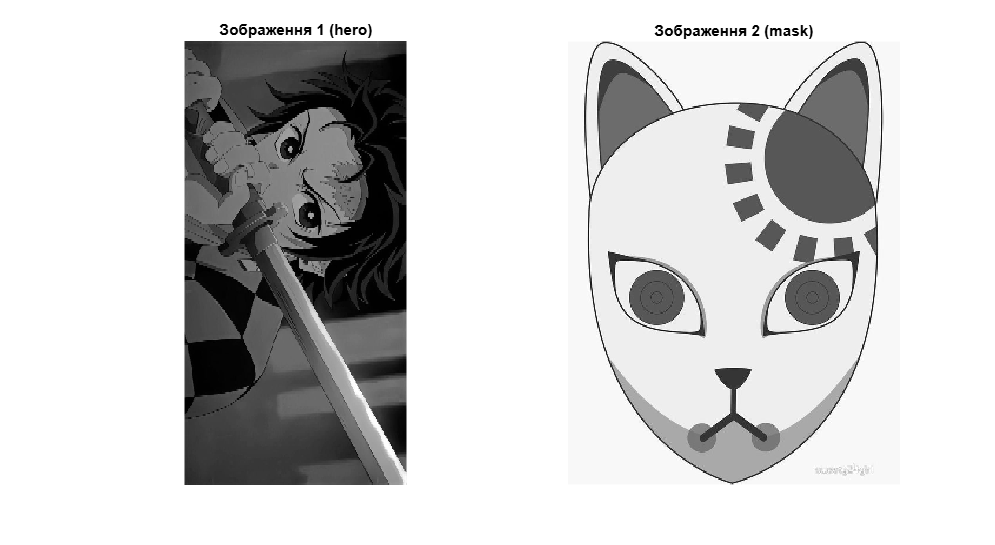

% Завантажуємо два зображення та конвертуємо в double відтінки сірого
origImage1 = imread('imgFolder/hero.jpg');
origImage2 = imread('imgFolder/mask.jpg');

if size(origImage1,3) == 3
    origImage1 = rgb2gray(origImage1);    % RGB->Grayscale
end
if size(origImage2,3) == 3
    origImage2 = rgb2gray(origImage2);
end

img1 = im2double(origImage1);
img2 = im2double(origImage2);

figure('Name','1. Оригінальні зображення','NumberTitle','off');
subplot(1,2,1), imshow(img1), title('Зображення 1 (hero)');
subplot(1,2,2), imshow(img2), title('Зображення 2 (mask)');
truesize;

## 2. Обчислення та відображення спектрів (без зсуву)

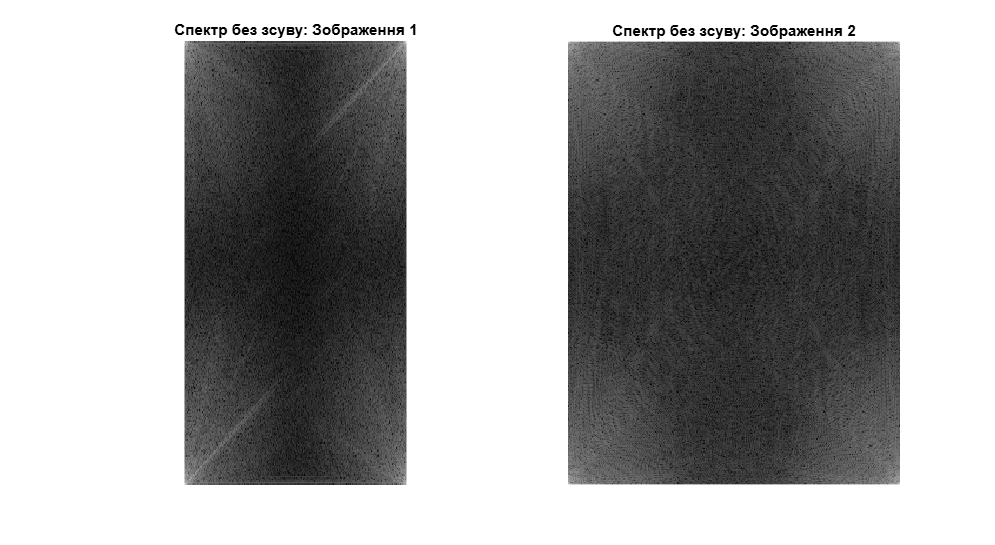

fftImg1 = fft2(img1);
fftImg2 = fft2(img2);

% Обчислюємо модуль (амплітуду) без зсуву
mag1_noShift = abs(fftImg1);
mag2_noShift = abs(fftImg2);

logMag1_noShift = log(1 + mag1_noShift);
logMag2_noShift = log(1 + mag2_noShift);

normMag1_noShift = mat2gray(logMag1_noShift);
normMag2_noShift = mat2gray(logMag2_noShift);

spec1_noShift = uint8(255 * normMag1_noShift);
spec2_noShift = uint8(255 * normMag2_noShift);

figure('Name','2. Спектри без fftshift','NumberTitle','off');
subplot(1,2,1), imshow(spec1_noShift, []), title('Спектр без зсуву: Зображення 1');
subplot(1,2,2), imshow(spec2_noShift, []), title('Спектр без зсуву: Зображення 2');
truesize;

## 3. Обчислення спектрів із fftshift

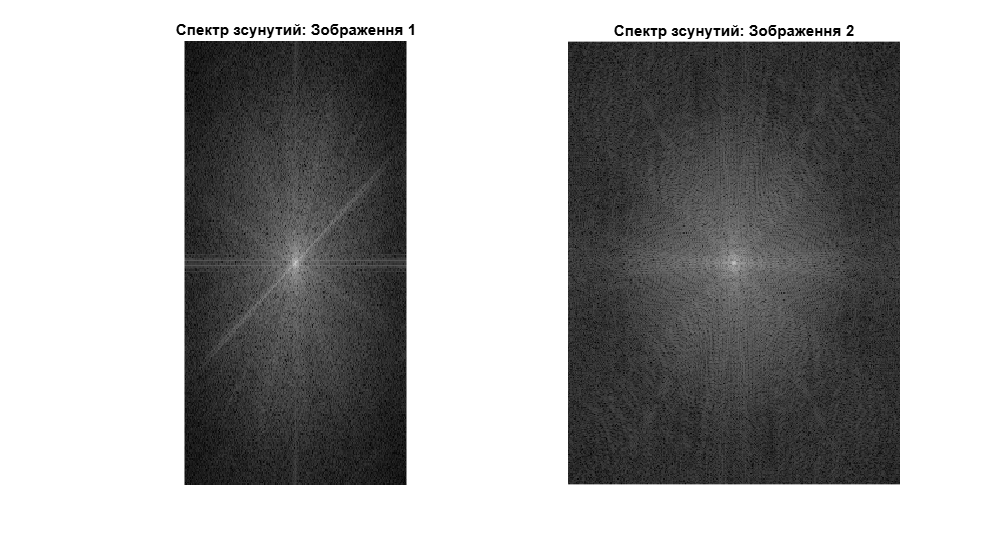

fftImg1_shift = fftshift(fftImg1);
fftImg2_shift = fftshift(fftImg2);

mag1_shift = abs(fftImg1_shift);
mag2_shift = abs(fftImg2_shift);

logMag1_shift = log(1 + mag1_shift);
logMag2_shift = log(1 + mag2_shift);

normMag1_shift = mat2gray(logMag1_shift);
normMag2_shift = mat2gray(logMag2_shift);

spec1_shift = uint8(255 * normMag1_shift);
spec2_shift = uint8(255 * normMag2_shift);

figure('Name','3. Спектри з fftshift','NumberTitle','off');
subplot(1,2,1), imshow(spec1_shift, []), title('Спектр зсунутий: Зображення 1');
subplot(1,2,2), imshow(spec2_shift, []), title('Спектр зсунутий: Зображення 2');
truesize;

## 4. Відновлення зображень з амплітудного спектру

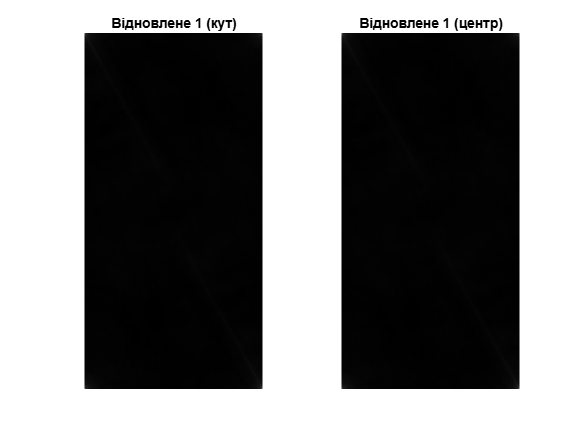

amp1 = abs(fftImg1);
amp2 = abs(fftImg2);

rec1_corner = ifft2(amp1);    % нульова частота у куті
rec2_corner = ifft2(amp2);

rec1_center = ifft2(ifftshift(amp1));  % нульова частота у центрі
rec2_center = ifft2(ifftshift(amp2));

figure('Name','4. Відновлення (амплітуда)');
subplot(1,2,1), imshow(abs(rec1_corner), []), title('Відновлене 1 (кут)');
subplot(1,2,2), imshow(abs(rec1_center), []), title('Відновлене 1 (центр)');

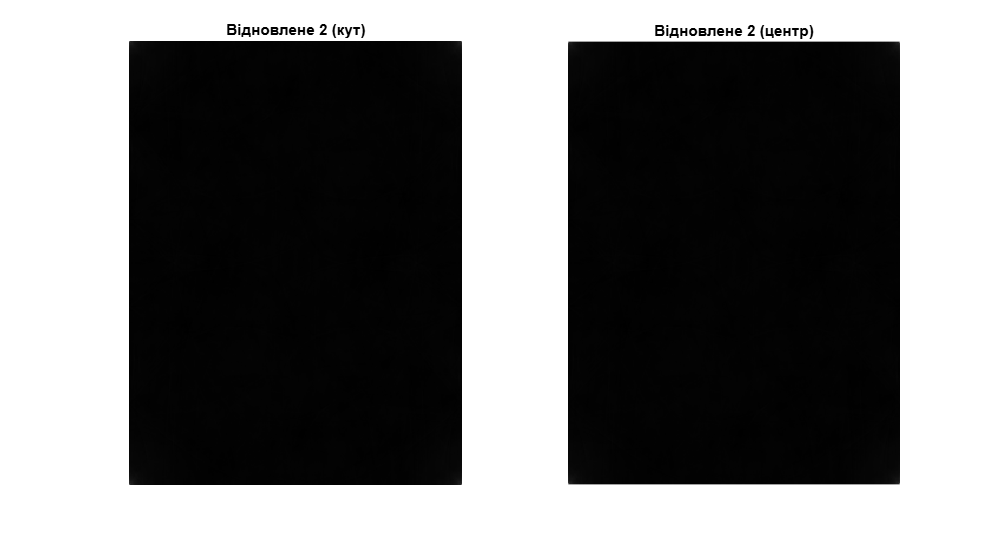


figure('Name','4. Відновлення (амплітуда) для 2');
subplot(1,2,1), imshow(abs(rec2_corner), []), title('Відновлене 2 (кут)');
subplot(1,2,2), imshow(abs(rec2_center), []), title('Відновлене 2 (центр)');
truesize;

## 5. Створення фільтрів Гауса та їх частотних характеристик

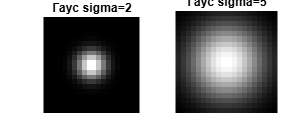

M = 20;  % розмір по вертикалі
N = 20;  % розмір по горизонталі
sigma_low = 2;
sigma_high = 5;

gaussLow = fspecial('gaussian', [M N], sigma_low);
gaussHigh = fspecial('gaussian', [M N], sigma_high);

figure('Name','5. Гаусові фільтри (простір)','NumberTitle','off');
subplot(1,2,1), imshow(gaussLow, []), title('Гаус sigma=2');
subplot(1,2,2), imshow(gaussHigh, []), title('Гаус sigma=5');
truesize;

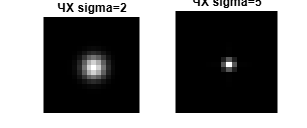


% Частотна характеристика фільтрів
fftGaussLow = fft2(gaussLow);
fftGaussHigh = fft2(gaussHigh);

figure('Name','5. ЧХ Гаусових фільтрів','NumberTitle','off');
subplot(1,2,1), imshow(abs(fftshift(fftGaussLow)), []), title('ЧХ sigma=2');
subplot(1,2,2), imshow(abs(fftshift(fftGaussHigh)), []), title('ЧХ sigma=5');
truesize;

## Крок 6: Фільтрація зображень у частотній області

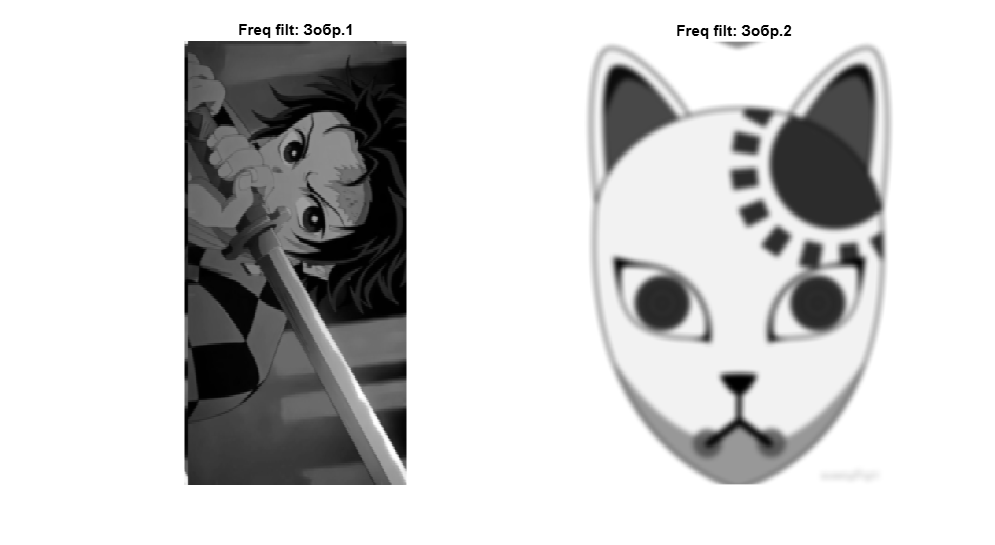

[rows1, cols1] = size(img1);
[rows2, cols2] = size(img2);

FFT1 = fft2(img1, rows1, cols1);
FFT2 = fft2(img2, rows2, cols2);

H1 = fft2(gaussLow, rows1, cols1);
H2 = fft2(gaussHigh, rows2, cols2);

prod1 = FFT1 .* H1;
prod2 = FFT2 .* H2;

filtImg1_freq = real(ifft2(prod1));
filtImg2_freq = real(ifft2(prod2));

figure('Name','6. Частотна фільтрація','NumberTitle','off');
subplot(1,2,1), imshow(filtImg1_freq, []), title('Freq filt: Зобр.1');
subplot(1,2,2), imshow(filtImg2_freq, []), title('Freq filt: Зобр.2');
truesize;

## 7. Фільтрація у просторі (conv)

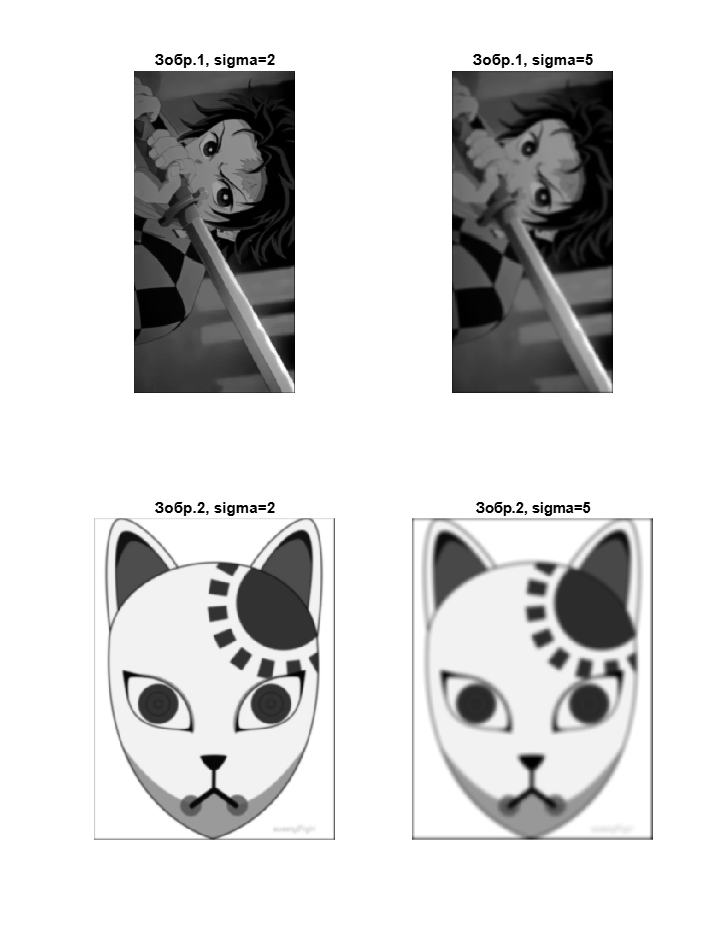

spatialImg1_low = imfilter(img1, gaussLow, 'conv', 'same');
spatialImg1_high = imfilter(img1, gaussHigh, 'conv', 'same');
spatialImg2_low = imfilter(img2, gaussLow, 'conv', 'same');
spatialImg2_high = imfilter(img2, gaussHigh, 'conv', 'same');

figure('Name','7. Просторова фільтрація','NumberTitle','off');
subplot(2,2,1), imshow(spatialImg1_low, []), title('Зобр.1, sigma=2');
subplot(2,2,2), imshow(spatialImg1_high, []), title('Зобр.1, sigma=5');
subplot(2,2,3), imshow(spatialImg2_low, []), title('Зобр.2, sigma=2');
subplot(2,2,4), imshow(spatialImg2_high, []), title('Зобр.2, sigma=5');
truesize;

## 8. Порівняння (Зобр.1)

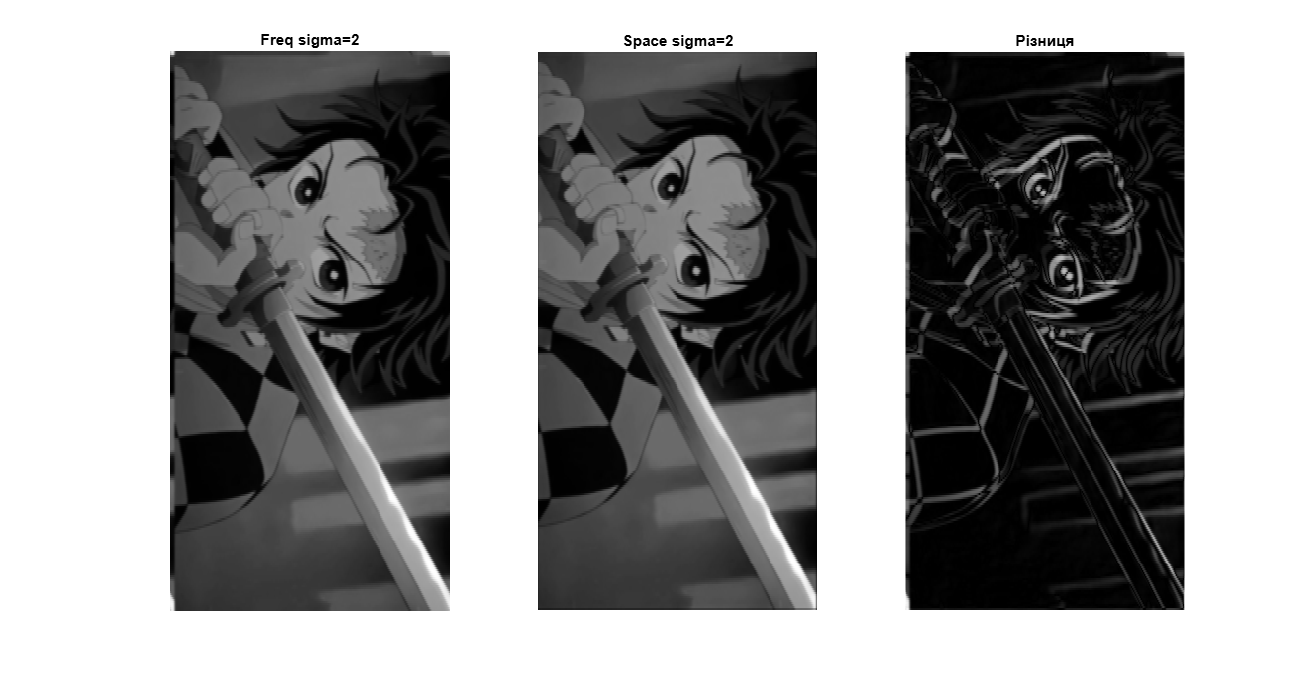

% Обчислюємо різницю між відфільтрованими зображеннями
diff1 = abs(filtImg1_freq - spatialImg1_low);

figure('Name','8.Порівняння Зобр.1','NumberTitle','off');
subplot(1,3,1), imshow(filtImg1_freq, []), title('Freq sigma=2');
subplot(1,3,2), imshow(spatialImg1_low, []), title('Space sigma=2');
subplot(1,3,3), imshow(mat2gray(diff1), []), title('Різниця');
truesize;

## 9. Порівняння (Зобр.2)

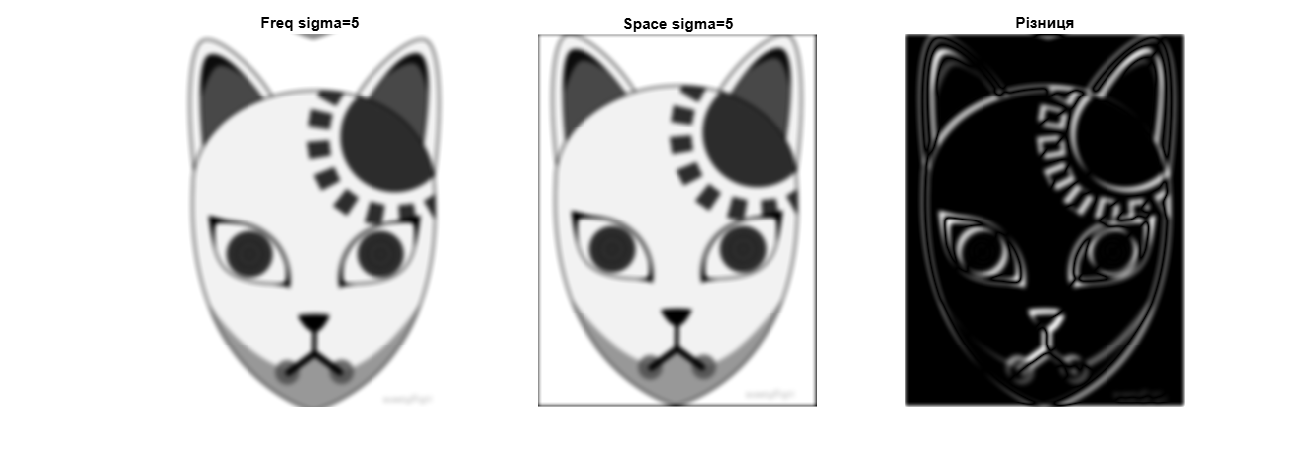

%Обчислюємо різницю між відфільтрованими зображеннями
diff2 = abs(filtImg2_freq - spatialImg2_high);

figure('Name','9. Порівняння Зобр.2','NumberTitle','off');
subplot(1,3,1), imshow(filtImg2_freq, []), title('Freq sigma=5');
subplot(1,3,2), imshow(spatialImg2_high, []), title('Space sigma=5');
subplot(1,3,3), imshow(mat2gray(diff2), []), title('Різниця');
truesize;